# Example 6.14: Applying Convolution Theorem to Filter Signal

Note: this script reproduces Example 6.14 (Section 6.3.2) of **Statistics for Chemical Engineers**: removing the high-frequency component of a signal with a Gaussian filter. Victor Z UW-Madison, 2019 illustrate fourier transform of different filters

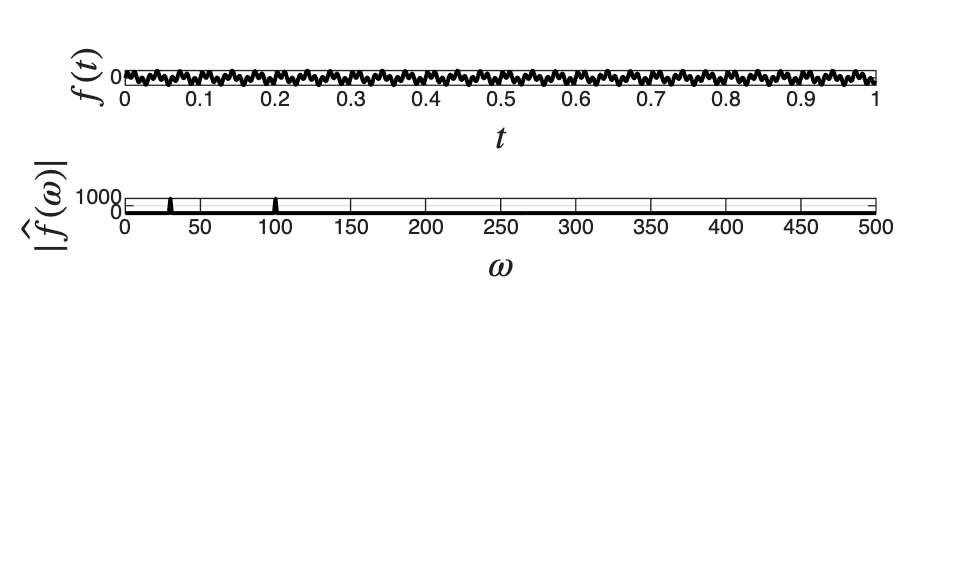

clc;  clear all; close all hidden; format short 

L = 1000;                                 % length of signal
Fs= 1000;                                 % Hz (sampling frequency)
T = 1/Fs;                                 % sec (sampling period)
t = (0:L-1)*T;                            % time vector
om = Fs*(0:(L/2))/L;                      % frequency vector

f1 = sin(2*pi*30*t);                      % low-frequency signal
f2 = sin(2*pi*100*t);                     % high-frequency signal
f = f1+f2;  

fh = fft(f);                              % compute DFT 
m = abs(fh);                              % magnitude
mf = m(1:L/2+1);                          % eliminate symmetry
mf(2:end-1) = 2*mf(2:end-1);

figure(1)
subplot(4,1,1)
plot(t,f,'black','LineWidth',1.5)
grid on
ylabel('$f(t)$','Interpreter','Latex','FontSize',14)
xlabel('$t$','Interpreter','Latex','FontSize',14)
subplot(4,1,2)
plot(om,mf,'black','LineWidth',1.5)
grid on
hold on
ylabel('$|\hat{f}(\omega)|$','Interpreter','Latex','FontSize',14)
xlabel('$\omega$','Interpreter','Latex','FontSize',14)

## Gaussian filter

gaussian filter

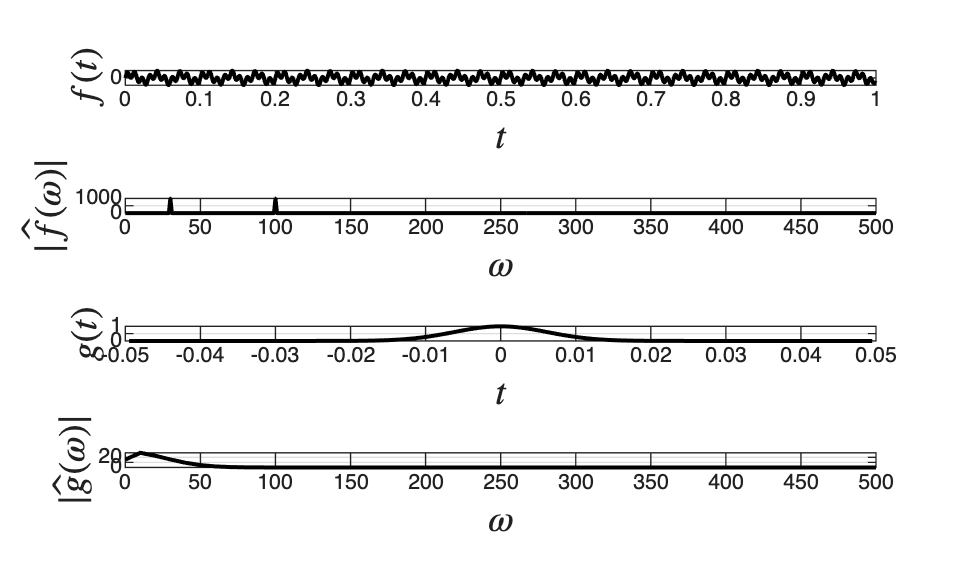

N = 100;
n = -(N-1)/2:(N-1)/2;
alpha = 8; % increase to increase cut-off frequency
w = gausswin(N,alpha);
stdev = (N-1)/(2*alpha);

wh = fft(w);                              % compute DFT 
m = abs(wh);                              % magnitude
mw = m(1:N/2+1);                          % eliminate symmetry
mw(2:end-1) = 2*mw(2:end-1);
om = (0:(N/2))/N;                      % frequency vector

figure(1)
subplot(4,1,3)
plot(n*T,w,'black','LineWidth',1.5)
grid on
ylabel('$g(t)$','Interpreter','Latex','FontSize',14)
xlabel('$t$','Interpreter','Latex','FontSize',14)
subplot(4,1,4)
plot(om*Fs,mw,'black','LineWidth',1.5)
grid on
ylabel('$|\hat{g}(\omega)|$','Interpreter','Latex','FontSize',14)
xlabel('$\omega$','Interpreter','Latex','FontSize',14)

print -depsc ch6_filter_gauss_fourier.eps

## Filtered signal

apply filter

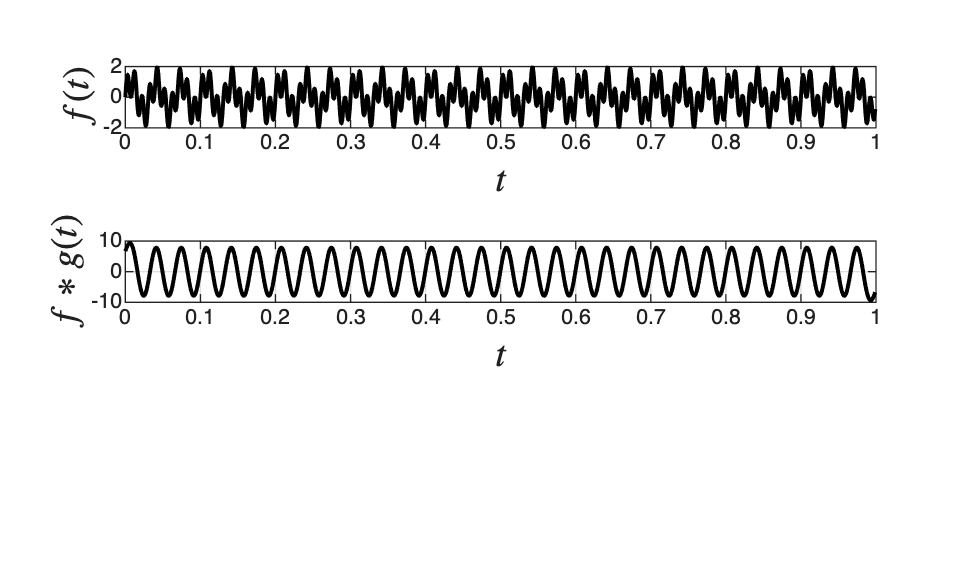

phi=conv(f,w,'same');

figure(2)
subplot(3,1,1)
plot(t,f,'black','LineWidth',1.5)
grid on
ylabel('$f(t)$','Interpreter','Latex','FontSize',14)
xlabel('$t$','Interpreter','Latex','FontSize',14)
subplot(3,1,2)
plot(t,phi,'black','LineWidth',1.5)
grid on
ylabel('$f*g(t)$','Interpreter','Latex','FontSize',14)
xlabel('$t$','Interpreter','Latex','FontSize',14)

print -depsc ch6_filter_gauss_fourier_elim.eps

## Note

As in the book, the filter removes the high-frequency component and keeps the low-frequency one, as the convolution theorem predicts.